# **Linear Algebra Group Project - Bethany Wu & Alex Stapley**

## **Problem 4: **Preconditioning GMRES

### Part a:

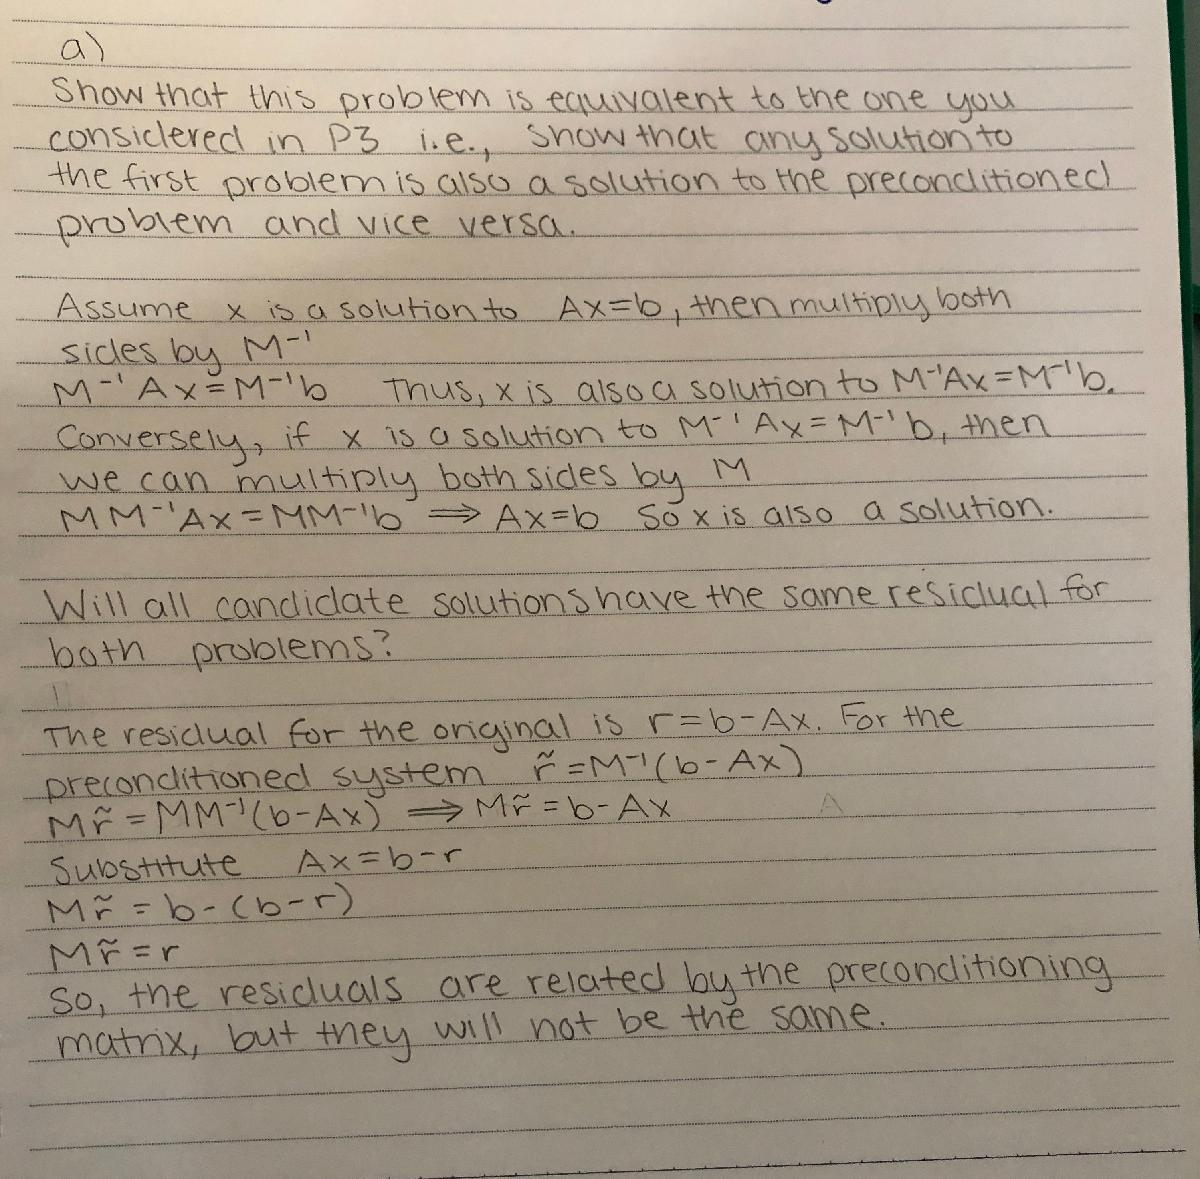

### **Part b:**

Argue that A~ and b~ can be calculated efficiently, even though they formally involve a matrix inverse.  (This is a requirement for a preconditioning matrix to be useful.)

A~ = A1^-1 A

b~ = A1^-1 A 

A is a tridiagonal matrix, therefore the inverse can be found easily. 

### **Part c: Solve the FEM Problem with the Preconditioned Matrix**

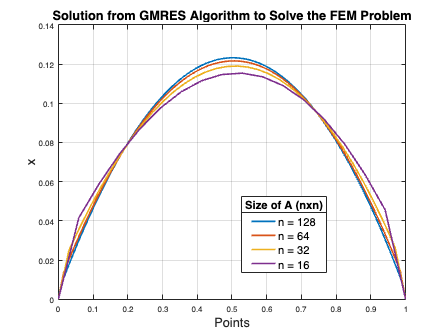

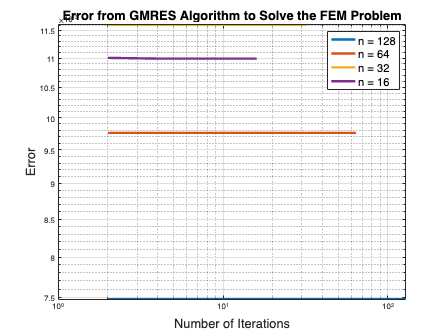

% For V(x) = 1
FEM_M(0);

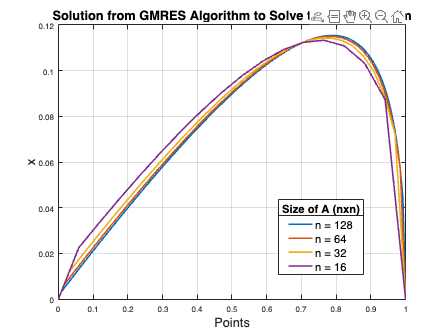

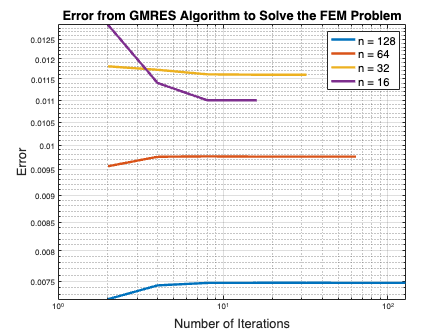

% For V(x) = n + 1
FEM_M(1);

**Part d: **How quickly does the convergence rate for your GMRES algorithm compare with that in problem 3?  Why?  (Hint: Consider the condition number of the two problems.)

ns = [128 64 32 16];
% For V(x) = 1
gamma=1;
for n=ns
    [A1,A,b] = BVPtoVar_A1(n,gamma);
    A_t = inv(A1).*A; b_t = inv(A1)*b;
    fprintf("Condition number of A for n=%d: %.4f",n,cond(A));
    fprintf("Condition number of A_tilda for n=%d: %.4f",n,cond(A_t));
end

Condition number of A for n=128: 6641.5371

Condition number of A_tilda for n=128: 127.0152

Condition number of A for n=64: 1685.7630

Condition number of A_tilda for n=64: 63.0302

Condition number of A for n=32: 434.0470

Condition number of A_tilda for n=32: 31.0596

Condition number of A for n=16: 114.7320

Condition number of A_tilda for n=16: 15.1160

% For V(x) = n+1
for n=ns
    gamma = n+1;
    [A1,A,b] = BVPtoVar_A1(n,gamma);
    A_t = inv(A1).*A; b_t = inv(A1)*b;
    fprintf("Condition number of A for n=%d: %.4f",n,cond(A));
    fprintf("Condition number of A_tilda for n=%d: %.4f",n,cond(A_t));
end

Condition number of A for n=128: 323.9814

Condition number of A_tilda for n=128: 124.3314

Condition number of A for n=64: 160.9510

Condition number of A_tilda for n=64: 61.5609

Condition number of A for n=32: 79.3595

Condition number of A_tilda for n=32: 30.2978

Condition number of A for n=16: 38.4365

Condition number of A_tilda for n=16: 14.7603

The preconditioned A_t is better than A because the preconditioner can help to improve the cond of a matrix A by converting to cond(M^−1A).  Also, it can reduce the calculation of a large matrix.

#### 'FEM' function for solving the finite-element formulation of the variational problem for different V(x) = gamma W/ PRECONDITIONING MATRIX

function FEM_M(m)
    ns = [128 64 32 16];
    Is = [2 4 8 16 32 64 128];
    error_thresh = 10e-6;
    figure(1);
    figure(2);
    for n = ns
        gamma = n*m+1;
        errors = []; iters = [];
        [A1,A,b] = BVPtoVar_A1(n,gamma);
        A_t = inv(A1).*A; b_t = inv(A1)*b;
        M = diag(ones(n,1));
        x0 = zeros(n,1);
        for I = Is
            % if I > n
            %     points = linspace(0,1,n+2);
            %     figure(2); plot(points,[0 x 0],'LineWidth',2); hold on;
            %     break;
            % end
            x = gmres_BA(I,b_t,x0,n,M,A_t);
            e = norm(b-A_t*x')/n;
            errors = [errors e];
            iters = [iters I];
            if e < error_thresh
                break;
            end
            if I == n
                points = linspace(0,1,n+2);
                figure(2); plot(points,[0 x 0],'LineWidth',2); hold on;
                break;
            end
        end
        figure(1); loglog(iters,errors,'LineWidth',3); hold on;
    end

    figure(1); title('Error from GMRES Algorithm to Solve the FEM Problem','FontSize',16);
    xlabel('Number of Iterations','FontSize',16); ylabel('Error','FontSize',16);
    legend('n = 128','n = 64','n = 32','n = 16','FontSize',14); grid on; hold off;

    figure(2); title('Solution from GMRES Algorithm to Solve the FEM Problem','FontSize',16);
    xlabel('Points','FontSize',16); ylabel('x','FontSize',16);
    leg = legend('n = 128','n = 64','n = 32','n = 16','FontSize',14); title(leg,'Size of A (nxn)','FontSize',14);
    grid on; hold off;
end

#### 'BVPtoVar_A1' (boundary value problem to variational problem) function that returns A1 (the preconditioned matrix)

function [A1,A,b] = BVPtoVar_A1(n,gamma)
    dx = 1/(n+1);
    % Forming A1
    side_A1 = ones(n-1,1)*(-1/(dx));
    diag_A1 = ones(n,1)*(2/dx); 
    A1 = diag(side_A1,-1)+diag(diag_A1)+diag(side_A1,1);
    % Forming A2
    side_A2 = ones(n-1,1)*(gamma/2);
    A2 = diag(-side_A2,-1)+diag(side_A2,1);

    A = A1+A2;
    b = ones(n,1)*dx;
end

#### The GMRES algorithm with inner product matrix, M (= identity matrix)

function x = gmres_BA(I,b,x0,n,M,A)
    r0 = b-A*x0;
    beta = norm(r0);
    V = zeros(n,n+1); W = zeros(n);
    V(:,1) = r0/beta;
    H = zeros(n+1,n); 
    for j = 1:I
        W(:,j) = A*V(:,j);
        for i = 1:j+1
            H(i,j) = dot(W(:,j),M*V(:,i));
            W(:,j) = W(:,j)-H(i,j)*V(:,i);
        end
        H(j+1,j) = norm(W(:,j));
        if H(j+1,j) == 0
            break;
        end
        V(:,j+1) = W(:,j)./H(j+1,j);
    end
    [n,m] = size(H);
    a = zeros(n,1); a(1) = beta;
    ys = lsqlin(H,a);
    for i = 1:length(ys)
        x(i) = V(i,1:length(ys))*ys;
    end
end